**Lab0**

**Objetivo: **determinar a frequência cardíaca a partir de um vídeo

**Passo 1: **ler o vídeo, criando um objeto de vídeo

video = VideoReader("ppg.mp4");

**Passo 2: **obtenção do sinal PPG

%vetor da dimensão do nr. de frames
signal = zeros(1,video.NumFrames); 
%iteração sobre cada frame
i=1;
while hasFrame(video)
    frame = readFrame(video);
    %média de todos os pixéis do canal vermelho (1)
    signal(i) = mean(frame(:,:,1),'all');
    i=i+1;
end

**Passo 3: **visualização do sinal PPG

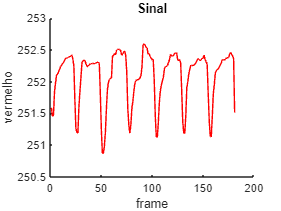

figure
hold on
plot(signal, "Color", [1 0 0])
title('Sinal')
xlabel('frame')
ylabel('vermelho')
hold off

**Passo 4: **definição dos mínimos do sinal

%definição de um threshold
belowT = signal > 251.5

belowT = 1×181 logical array
   1   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0


%extremos locais do sinal
minima = islocalmin(belowT)

minima = 1×181 logical array
   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


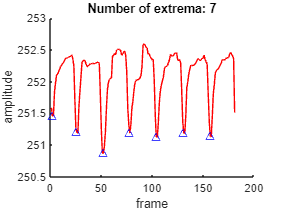

%visualização dos mínimos
figure
hold on
plot(signal, "Color", [1 0 0])
plot(find(minima), signal(minima), "^", "Color", [0 0 1])
title("Number of extrema: " + nnz(minima))
xlabel('frame')
ylabel('amplitude')
hold off

**Passo 5: **cálculo do ritmo cardíaco

%nr. de mínimos
disp(nnz(minima))

     7



%valor do último mínimo
disp(signal(nnz(minima)))

  252.1187



%por análise do gráfico último mínimo ~ frame 157 (idealmente não é a olho)
time = 157/floor(video.FrameRate)

time = 5.4138

ppg = (nnz(minima)/time)*60

ppg = 77.5796